## Plot 3: A surf plot of the variability (standard deviation divided by mean) for the entire record of the maximum annual value

clear all; close all;
load('Entire_region.mat') 

t = T{:,3:22}';
variability = std(t)./mean(t);
variability = variability'

variability =     0.4230
    0.4230
    0.8700
    0.2679
    0.4480
    0.4480
    1.3584
    1.3584
    0.4994
    0.4994


clear t;

RGB = [254,229,217
    252,187,161
    252,146,114
    251,106,74
    239,59,44
    203,24,29
    153,0,13];

A = ~isnan(ndvi(:,:, 15));
Z_variability = [];
x = 0;
for i = 1:nc
    z_variability_col = [];
    indx = find(A(:,i)>0);
    start_indx = indx(1);
    end_indx = indx(end);
    z_variability_col(1:start_indx-1) = NaN;
    z_variability_col(indx)=variability(x+1: x+length(indx));
    z_variability_col(end_indx+1:nr) = missing;
    x = x+length(indx);
    Z_variability = [Z_variability z_variability_col'];
end
clear A; clear end_indx; clear start_indx; clear i; 
clear x; clear z_variability_col; clear variability; clear indx

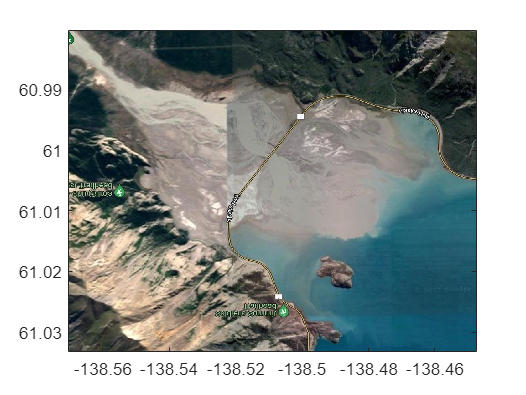

img=imread('Yukon_delta.jpg'); 
image([ -138.447718 -138.570218],[61.033109 60.980258], img);
hold('on');

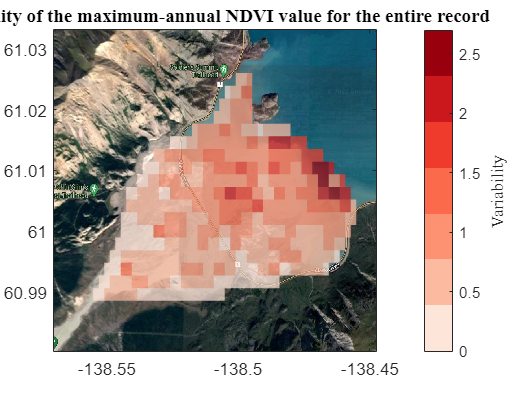

[nr,nc]=size(Z_variability);
s= pcolor([X(:,1);nan],[Y(1,:), nan],[Z_variability nan(nr,1); nan(1,nc+1)]' );
s.EdgeColor = 'none' ;
s.FaceAlpha = 0.7;

c = colorbar; 
c.Label.String = 'Variability';
c.Label.FontName = 'Dialog';
c.Label.FontSize = 10;
colormap(RGB./255);

%xlabel("Longitude"); ylabel("Latitude"); 
title("Variability of the maximum-annual NDVI value for the entire record ", 'FontName', 'Dialog')

set(gca, 'xDir', 'reverse') 
set(gca,'XAxisLocation','top','YAxisLocation','right','ydir','reverse');
camroll(180)
hold off;

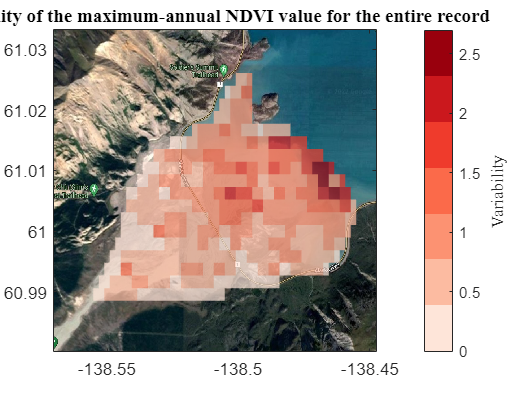

saveas(gcf,'Published_Plots\Figure_7.pdf')

clear c; clear s; 